# Rattle sound analysis

This script takes a .mat file, containing rattling audio data, and analyzes it for loudness and frequency. 

## Analysis parameters

Input parameters for 1) parameters at which the audio was recorded and 2) the desired analysis settings. 

fs=44100; %sampling rate of the audio signal

fftpts=256;     %points used to generate the fft
env_fftpts=128;     %points used for generating the soudn envelope
loudness_integration=128;   %points used for integration to calculate loudness
moving_average_duration=200;    % moving average for resampling/loudness calc
fhigh=1e3; %high-pass filter cutoff
lower_modulation_threshold=4;   %% change together with env_fftpts: analyzes only frequencies above mf(modulation_lower_threshold)
f=linspace(0,fs,fftpts);    %frequency domain
LF_ulim=30; %upper limit for low frequency rattling
HF_llim=60; %lower limit for high frequency rattling

## Importing data

Load in a file from a preselection. 

rattleFiles = dir("snake_data" + filesep + "*.mat");
rattleFiles = string({rattleFiles.name}');
filename = rattleFiles(1)

filename = "CaR008_prestim2_rise10_sustain5_decay10_poststim5_maxcd500_m1.mat"

load("snake_data" + filesep + filename)
load("snake_data/" + filename)

### Noise filter

Filter the signal with a butterworth high-pass filter and generate the corresponding time vector. 

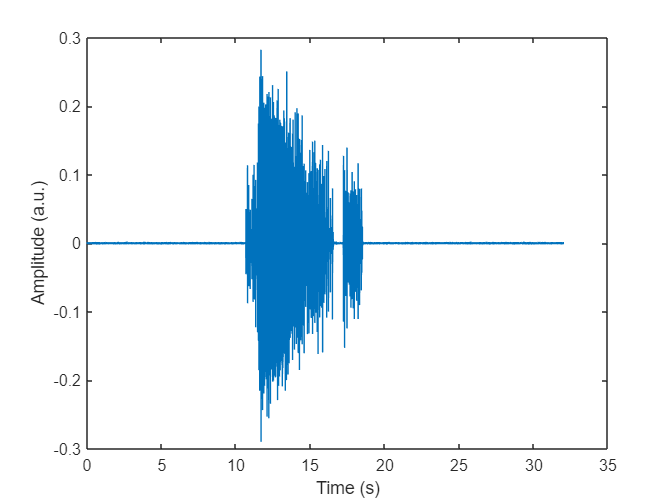

[b,a]=butter(2,2*fhigh/fs,'high');
rattle=filtfilt(b,a,double(squeeze(audiorec(:,1))));
rattle_time=(0:length(rattle)-1)/fs;
plot(rattle_time, rattle)
xlabel('Time (s)')
ylabel('Amplitude (a.u.)')

### Extraction of stimulus settings

Get the stimulus size from the filename of the recording. 

startind=strfind(filename,'maxcd')+5;
stopind=max(strfind(filename,'_'))-1;
maxcd=str2double(extractBetween(filename,startind,stopind));

Get the stimulus start time from the filename of the recording. 

startind=strfind(filename,'prestim')+7;
stopind=strfind(filename,'_rise')-1;
stim_onset=str2double(extractBetween(filename,startind,stopind));

## Processing of the audio signal

### Conversion to tail shake signal

Rectify and then downsample the signal to calculate the envelope, which reduces the signal generated by individual elements of the rattle snake rattle during a tail shake, and leaves the signal of tail shakes as a whole.

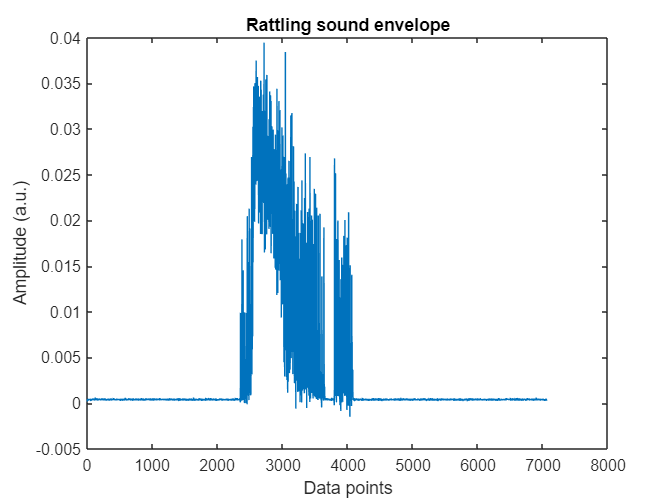

env=resample(abs(rattle),1,moving_average_duration);
plot(env)
title('Rattling sound envelope')
ylabel('Amplitude (a.u.)')
xlabel('Data points')

### Loudness calculation

Calculate relative loudness as a function of time, using both the moving average duration and the loudness integration window set above. 

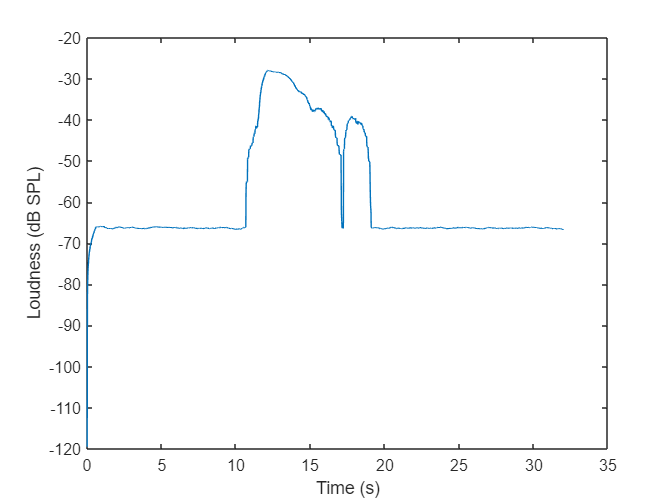

loudness=20*log10(sqrt(filter(ones(moving_average_duration*loudness_integration,1),moving_average_duration*loudness_integration,rattle.^2)));
plot(rattle_time, loudness)
xlabel('Time (s)')
ylabel('Loudness (dB SPL)')

[~,scff,scft,p]=spectrogram(rattle,fftpts,fftpts/2,fftpts,fs); 

## Plotting

Plot a summary figure for frequency, modulation frequency, loudness and rattle frequency in dependence on the stimulus.

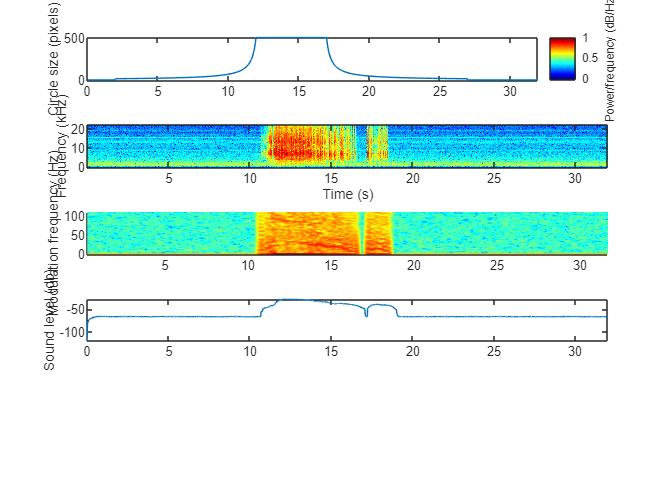

figure
sft=(0:length(scalefactors)-1)*ifi;
subplot(5,1,1), plot(sft,scalefactors*maxcd)
axis tight
title(filename)
ylabel('Circle size (pixels)')

subplot(5,1,2),
spectrogram(rattle,fftpts,fftpts/2,fftpts,fs,'yaxis');
colormap jet
axis tight

subplot(5,1,3),
[~,mf,mt,mp]=spectrogram(env,env_fftpts,round(env_fftpts*0.95),env_fftpts,fs/moving_average_duration,'yaxis');
surf(mt,mf,10*log10(abs(mp)),'edgecolor','none');
axis xy; axis tight; colormap(jet); view(0,90);
ylabel('Modulation frequency (Hz)')

subplot(5,1,4),
plot(rattle_time,loudness)
axis tight
ylabel('Sound level (db)')

## Rattle frequency calculation

Extraction of the dominant rattling frequency from the modulation spectrogram. Takes every bin of the modulation spectrogram and finds the index with the highest frequency content above a certain frequency (4.3), and only if it crosses a certain modulation power (3e-8).

rfs=zeros(size(mt));
for bn=1:length(mt)
    mpx=mp(lower_modulation_threshold:end,bn);   % analyse only for mfs >= 4.3 Hz
    if max(mpx)>3e-8   % analyse only if modulation power above a threshold
        [~, rfs(bn)]=max(mpx);
    end
end

Where modulation was found, use the indices found above to index into the frequency space. 

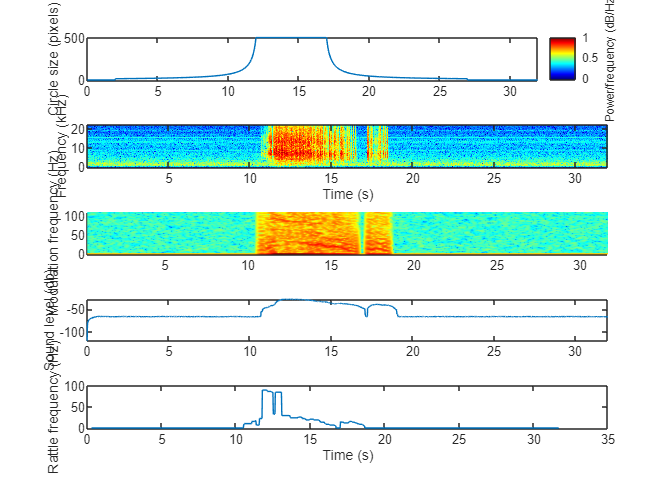

rfs(find(rfs))=mf(rfs(find(rfs)))+mf(lower_modulation_threshold);
subplot(5,1,5), plot(mt,rfs);
xlabel('Time (s)')
ylabel('Rattle frequency (Hz)')

## Data extraction 

### Validity of the recording 

To verify if this is a valid recording, show the position of the snake at three frames before, at and after stimulus onset. Note that example files in the repository have part of their video data removed past the initial 4 s for file size reasons. The code used for this is commented out. 

While the original images are stored in greyscale, images are brightened for better contrast and thus visibility of the snake. 

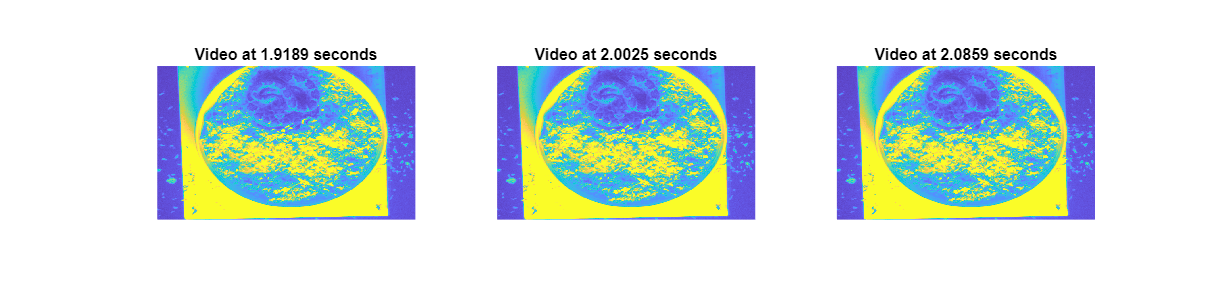

% % video only needed in the very beginning around video onset - remove rest
% % to get files <25 mb
% cutVideoAfterInd = find(videotime>4, 1, "first"); % cut video early, after 4 seconds
% videotime = videotime(1:cutVideoAfterInd);
% videorec = videorec(:,:,:,1:cutVideoAfterInd);
% % save data with less video frames
% save("snake_data_smaller\" + filename, "videorec","audiorec","scalefactors", "ifi","timestamp","videotime","videometa")


stimstart= sft(min(find(scalefactors>0)));
[mist,video_ind]=min(abs(videotime-stimstart));
figure,
set(gcf,'position',[13         573        1639         402])
for fn=1:3
    framenum=video_ind-2+fn;
    subplot(1,3,fn), imshow(squeeze(videorec(:,:,1,framenum)));
    brighten(0.1);
     title(['Video at ' num2str(videotime(framenum)) ' seconds'])
end

### Stimulus data

Store data about onset, duration and size of the stimulus into matlab variables. 

Animal_Nr = str2double(extractBetween(filename,"CaR","_prestim"));
Prestimulus_duration=str2double(extractBetween(filename, strfind(filename,'prestim')+7, strfind(filename,'_rise')-1));
Rise_duration=str2double(extractBetween(filename, strfind(filename,'rise')+4, strfind(filename,'_sustain')-1));
Sustain_duration=str2double(extractBetween(filename, strfind(filename,'sustain')+7, strfind(filename,'_decay')-1));
Decay_duration=str2double(extractBetween(filename, strfind(filename,'decay')+5, strfind(filename,'_poststim')-1));
Poststimulus_duration=str2double(extractBetween(filename, strfind(filename,'poststim')+8, strfind(filename,'_maxcd')-1));
Maximum_size=str2double(extractBetween(filename, strfind(filename,'maxcd')+5, strfind(filename,'.mat')-4));

### Rattling data

#### Processed rattling

Store data about rattling into matlab variables. 

modulation_time = mt;
rattle_modulation_frequency = rfs;
loudness_time = rattle_time;

#### Calculation of rattling phases and durations

Find where the snake rattles, and how the time course of rattling modes is (Low frequency into high frequency, low frequency only, or start with high frequency). 

rattling_inds=find(rfs>2);                      %find rattling, defined as activity at least above 2 Hz.
LFrattling_inds=find(rfs>0&rfs<=LF_ulim);       %Define LF rattling
HFrattling_inds=find(rfs>HF_llim);                          %Define HF rattling

%check for rattling type. 1 is LF ->HF, 2 LF only, 3 is HF start
if length(HFrattling_inds)<1&&length(LFrattling_inds)>2
    HFstatus=2;
end

if length(LFrattling_inds)>1&&length(HFrattling_inds)>2
    HFstatus=1;
end

if ~isempty(HFrattling_inds)
    if length(find(LFrattling_inds<HFrattling_inds(1)))<1&&~isempty(HFrattling_inds) %check if there is LF rattling before HF ->HF start
        HFstatus=3;
    end
end

Terminate the script if rattling does not fall into the low to high frequency pattern. 

if HFstatus==2 
    'Script terminated. Rattling has no HF rattling'
elseif HFstatus==3 
    'Script terminated. Starts with HF'
elseif HFstatus==1

#### Storage of rattling phases and duration

If rattling follows the "standard response", calculate duration and slope of the low and high frequency component respectively, as well as the latency to start rattling from stimulus onset. 

    %low frequency duration and slope
    initial_LF_inds = LFrattling_inds(LFrattling_inds<HFrattling_inds(1)); 
    HFshift_ind = HFrattling_inds(1); 
    initial_LF_time = modulation_time(initial_LF_inds); %rattle timepoints
    initial_LF_rattling = rfs(initial_LF_inds); %initial rattling segment
    start_latency = initial_LF_time(1)-stim_onset; %rattling latency
    initial_rattling_duration = initial_LF_time(end)-initial_LF_time(1); %initial LF duration
    
    padded_time=[ones(length(initial_LF_inds'),1) initial_LF_time'];
    ycorrected_fit_time=padded_time\initial_LF_rattling';
    slope_LF = ycorrected_fit_time(2);
    
    %high frequency duration and slope
    
    initial_HF_end = find(diff(HFrattling_inds)>2);
    initial_HF_end(end+1) = length(HFrattling_inds);
    initial_HF_end = initial_HF_end(1);
    initial_HF_inds = HFrattling_inds(1:initial_HF_end);
    
    initial_HF_time = modulation_time(initial_HF_inds); %rattle timepoints
    initial_HF_rattling = rfs(initial_HF_inds); %initial rattling segment
    initial_HF_duration = initial_HF_time(end)-initial_HF_time(1);
    
    padded_time=[ones(length(initial_HF_inds'),1) initial_HF_time'];
    ycorrected_fit_time=padded_time\initial_HF_rattling';
    slope_HF = ycorrected_fit_time(2);

    Titles = {'snake Nr'; 'approach duration'; 'start latency'; 'initial LF duration';'LF_slope';'initial HF duration';'HF slope'};
    Values = [Animal_Nr; Rise_duration; start_latency;initial_rattling_duration;slope_LF;initial_HF_duration;slope_HF];
    T = table(Values,'RowNames',Titles)

else
    'No analyzable LF-HF rattling found'
    
end

T = 7×1 table
                           Values 
                           _______

    snake Nr                     8
    approach duration           10
    start latency           8.5215
    initial LF duration     1.2245
    LF_slope                7.1019
    initial HF duration    0.70748
    HF slope               -8.7734
